# Authors: Marta Barriendos & Ana Garcia Armada, Univesidad Carlos III de Madrid

# 6G Waveforms Proposals

## Introduction

After implementing the previous notebook waveforms (CE-OFDM \& FM-OFDM), that were based on some modifications performed to the original OFDM signal, a new approach completely different to OFDM that looks like a promising alternative for 6G, called OTFS, is going to be explored. 

### Index

- Introduction to 6G

- Constant Envelope OFDM (CE-OFDM)

- Frequency modulated OFDM (FM- OFDM)

- Orthogonal Time Frequency Space (OTFS)

## 4. Orthogonal Time Frequency Space (OTFS)

Orthogonal Time Frequency Space (OTFS) modulation is a **2D modulation scheme** that operates in the **delay-Doppler domain**, unlike OFDM, which works in the time-frequency domain. It is a multicarrier modulation technique, resilient in channel environments with high-Doopler mulitpaths. Although most modern wireless systems use OFDM, the inability of this technique to cancel ICI makes them suffer in high- Doppler channels, which is why OTFS is very useful. 

**OTFS Motivation**

Throughout all these years, OFDM has been the most common modulation scheme for many wireless systems, however, this technique has two main drawbacks, the high-Doppler channel environments require frequent channel measurements, and they experiment a significant ICI:

- **OFDM transmits data in the time-frequency (TF) domain**, with each data symbol in its own orthogonal frequency subcarrier. Some pilots (refence) symbols are used, to measure and estimate the channel, however, they occupy an important part of the transmission bandwidth. Moreover, these pilots must be transmitted frequently because of the rapidly changing channel characteristics. Since when these pilots are transmitted, data cannot, they have the inconvenience of reducing the throughput.

- In high-Doppler multipath channels, **OFDM experiences inter-carrier interference (ICI) **when different signal paths have varying frequency offsets. These offsets arise due to the different relative velocities of the scatterers, leading to signal distortion. The frequency shifts from the different paths destroys the frequency domain orthogonality that is necessary for interference-free symbol detection.

OTFS modulation reduces the necessity of doing frequent channel measurements by continuosly transmitting data in the **delay-Doppler domain, **since it naturally represents moving scatterers based on their delay (transmission delay) and speed (Doppler shift) relative to the receiver. Since there are usually only a few scatterers, the channel can be represented as a sparse matrix (the delay-Domain channel matrix is mostly zero except for a few non-zero entries that represent the scatterers), making estimation and equalization more efficient. Moreover, if the scatterers move at a constant velocity, the channel remains stable in this domain, reducing the need for frequent pilot signals and improving overall data throughput.

Therefore, thanks to the resilience that OTFS presents to high-Doppler channels, it was considered as a modulation candidate for 5G NR and is being considered as a modulation candidate for 6G to meet new requirements for high-speed use cases.

**OTFS Data Grid**

As commented in the previous section, in OFDM information symbols are transmitted over a single time-frequency resource, which is susceptible to frequency and time selective fading effects, that will degrade the performance in high mobility wireless channels. However,  OTFS multiplexes each information symbol over a two dimensional orthogonal basis function, that spans the entire time and frequency resources, which means that all information symbols will experience a fixed (time-invariant) flat fading equivalent channel. 

We consider an OTFS system operating in a ***P-path high-mobility channel*** with bandwidth **B**, maximum delay spread ***τ_max***, and maximum Doppler shift ***ν_max***. The **discrete-time baseband model** samples the continuous-time OTFS signal at a frequency ***f_s = B = 1/T_s***, where ***T_s*** is the sampling interval.

An **OTFS frame** consists of ***NM***** samples**, structured into ***N***** time slots**, each containing ***M***** samples**. The total frame duration is ***T_f = NMT_s = NT***, with each block lasting ***T = M T_s***. Every ***T***** seconds**, an **M-point discrete Fourier transform (DFT)** is applied, producing a spectrum with frequency spacing ***Δf = 1/T***. The collection of the **N spectrums** over the time axis defines the **discrete time-frequency domain**, represented as an **M x N matrix *****X_tf[l,k]***, where **l = 0,...,M-1** and **k = 0,...,N-1**. Each column corresponds to a block’s spectrum.

To convert the **time-frequency domain** into the **delay-Doppler domain**, a **2D symplectic Fourier transform** is applied:

- **Inverse Fourier Transform** along the **frequency axis (columns)**

- **Fourier Transform** along the **time axis (rows)**

This transformation produces the **delay-Doppler domain**, represented as an **M x N matrix *****X[m,n]***, where **m = 0,...,M-1** and **n = 0,...,N-1**. The resolution of the delay and Doppler shifts is ***1/(MΔf)*** and ***1/(NT)***, respectively. This means that paths with **differences smaller than these resolutions cannot be distinguished** by the receiver.

This representation enables more efficient detection and equalization in high-mobility scenarios by leveraging the **sparsity of the channel** in the delay-Doppler domain, and it is presented in the following figure.

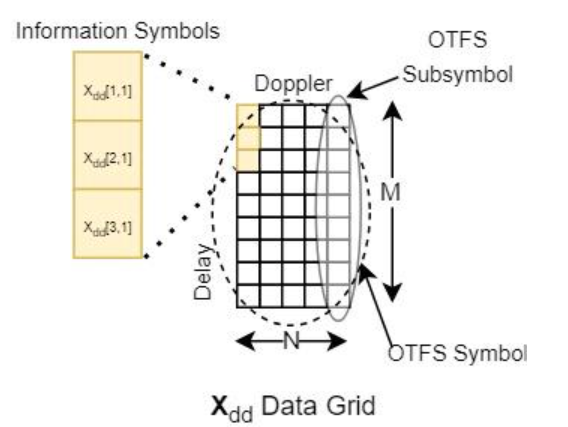

To conclude, the OFDM symbols are going to be mapped to an MxN transmit data grid *Xdd*[*k*,*l*], like the one  in the previous image, that represents the delay-Doppler domain,  where *k* is the delay axis index, *k*=0,1,...,*M*−1, and *l* is the Doppler axis index, *l*=0,1,...,*N*−1. The previous grid represents one OTFS symbol, and each column in the grid is a subsymbol. Finally, the indices *k* and *l* relate to the actual delay and Doppler shift by the relationship delay = *k*/(*M*∗*Δf*) and Doppler = *l*/(*N*∗*T*), where *Δf* is the subcarrier spacing in Hertz and *T* is the duration of an OTFS subsymbol in seconds, including any cyclic prefix. The indices *k* and *l* are the normalized delay and normalized Doppler shifts.

**Delay-Doppler Domain**

Operating in the **delay-Doppler domain** is similar to how a radar processes the reflected signals in **pulse Doppler radar systems**. The mechanisim is presented in the following figure. Firstly,  a radar emits a narrowband pulse to determine the distance of objects based on the **time delay** of the returning echoes, while their relative speed is measured using the **Doppler shift**. This is similar to what happens in a wireless communication, where a transmitted signal reaches the receiver through multiple paths, like radar echoes reflecting off different objects. Each reflected signal experiences a **specific delay**, depending on the path length, and a **Doppler shift**, influenced by the motion of the reflector relative to the receiver.

In the diagram, a **base station** transmits a signal to a **moving car**. The **two-dimensional delay-Doppler channel response, *****H_dd***, shown in the upper right, represents the different propagation paths. The **size of the numbers and thickness of the lines** correspond to the strength of each path.

- The **direct line-of-sight (LOS) path** serves as the reference, with **zero delay** and a **thick line** indicating its strong signal strength. The car is traveling **toward the base station at 130 km/h**, but since the receiver compensates for Doppler shift, the **Doppler index remains zero**.

- **Path 1** represents a reflection from a **nearby truck moving slower than the car**. This path has a **slightly longer delay** because the signal travels a greater distance, and it has a **negative Doppler shift**, as the car is moving away from the truck.

- **Path 2** comes from a **police car moving toward the receiving car** but at a **greater distance**. This reflection has a **longer delay**, a **positive Doppler shift**, and a **weaker signal strength** due to the increased distance.

Thanks to this delay-Doppler representation, it is possible to analyze how signals interact with the environment in high-mobility scenarios, improving the ability to **track multipath reflections and compensate for Doppler effects** efficiently.

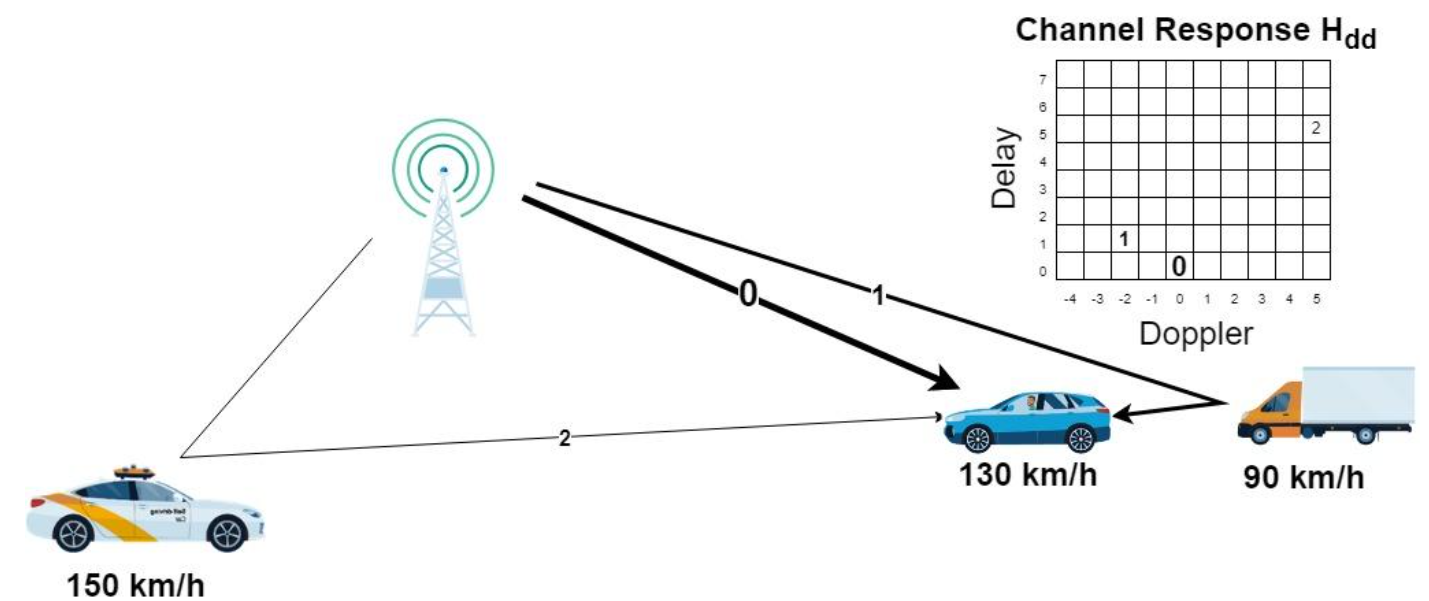

The effect of the multipath on a single grid element is shown below. ***Xdd*** contains five transmitted signals and ***Hdd*** is the channel response. ***Ydd*** is the 2-D convolution of *Xdd* and *Hdd*. In OTFS, since signal is time limited, the convolution will be circular, including phase rotation, which is known as ***twisted convolution***.

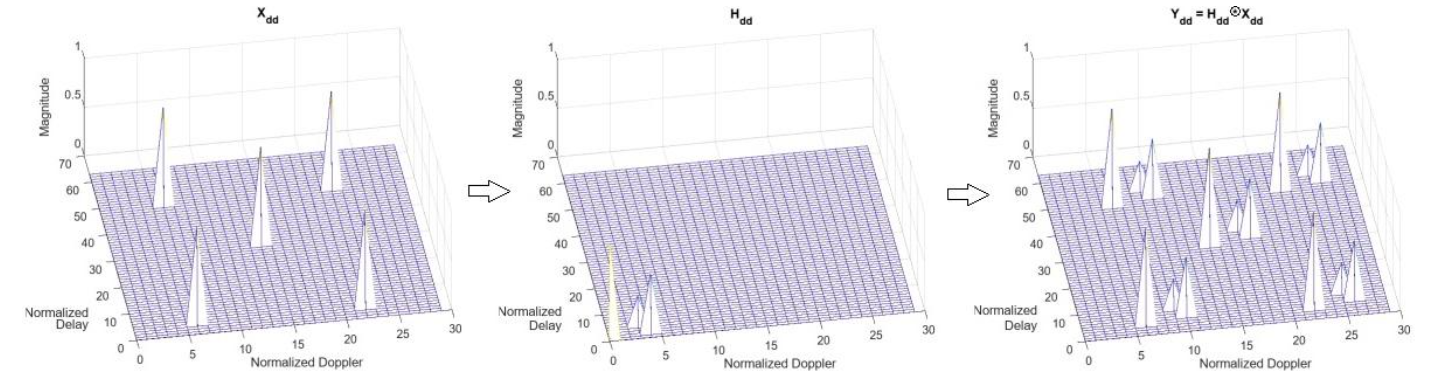

**Implementation**

The first step to implement this modulation scheme consists of defining the** OTFS Parameters** for the transmitter side:

- N: Number of **Doppler bins** (time slots)

- M: Number of **delay bins** (subcarriers)

- Δf: Subcarrier spacing

- T: Block duration

- Fn: **Normalized DFT matrix** (used for spreading across the Doppler domain)

- P: **Permutation matrix**, which rearranges symbols between time and frequency

These parameters define the **OTFS grid** and its resolution in both **delay** and **Doppler domains**.

%% PARAMETERS
N=16; % number of Doppler bins (time slots)
M=64; % number of delay bins (subcarriers)
Fn=dftmtx(N); 
Fn=Fn/norm(Fn); % normalized DFT matrix
delta_f=15e3; % subcarrier spacing
T=1/delta_f; % block duration
fc=4e9; % carrier frequency
c=299792458; % speed of light

% OTFS grid resolution
delay_resolution = 1/(M*delta_f); 
Doppler_resolution = 1/(N*T);
SNR_dB = 25; % Signal-to-noise ratio
mod_size=4; % QAM modulation order

***N***, ***M*** and*** T*** (f=1/T) are key design parameters for the OTFS System. For example, ***T*** and ***f*** will determine the maximum supportable channel delay, $\tau_{\max } \le \frac{f}{2}$. Therefore, if the data rate is fixed to ***NM*** symbols per frame, depending on the channel parameters, a larger*** T*** (smaller*** f*** ) can be chosen, resulting in a smaller ***N*** and larger ***M***, or vice versa. This means that OTFS can handle channels up to $\tau_{\max } \times \nu_{\max } \le \frac{1}{2}$ , which expands the opportunities to design systems working beyond underspread channels ($\tau_{\max } \times \nu_{\max } \ll \frac{1}{2}$). Another design constraint for OTFS systems lies in the assumption that the multipath channel parameters ${g_{i\;} ,\;\tau }_i {\;,\;\nu }_i$  are constant over the duration of the frame. This limits ***Tf*** to a maximum of 10–20 ms in today’s cellular system environment.

Once the corresponding parameters are defined, the **modulated symbols** are generated. In order to do this, some random bits are generated for transmission, applying the **QAM modulation** to convert the bits into symbols. The constellation of the final QAM symbols is presented below. 

%% TRANSMITTER
N_syms_per_frame=N*M;
N_bits_per_frame=N*M*log2(mod_size);

tx_info_bits=randi([0,1],N_bits_per_frame,1);
tx_info_symbols=qammod(tx_info_bits,mod_size,'gray','InputType','bit');

% Plot Transmitted Constellation
figure;
plot(tx_info_symbols, 'bo');
title("Transmitted QAM Constellation");
xlabel('In-phase'); ylabel('Quadrature');
grid on; axis equal;

**OTFS Modulation**

As illustrated in the following figure, at the transmitter, the ***NM*** information symbols must be placed in the delay-Doppler domain matrix $X\;\epsilon \;C^{M\times N}$ with entries*** X[m,n]***, for *m=0,...,M−1,n=0,...,N−1*. Therefore, the first step is for the transmitter to map the symbols ***X[m,n]*** to NM samples ***Xtf[l,k]*** on the time-frequency grid*** Λ*** via inverse symplectic fast Fourier transform (ISFFT). 

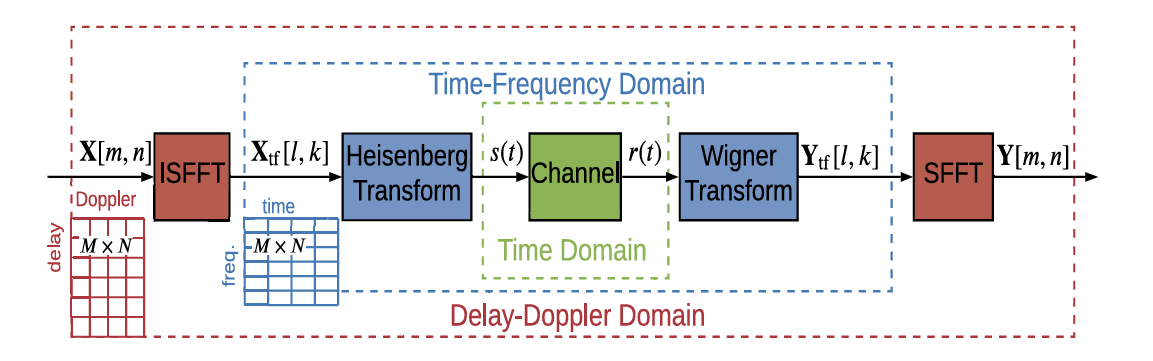

(DELAY-DOPPLER COMMUNICATIONS: Principles and Applications, *Yi Hong, Tharaj Thaj and Emanuele Viterbo*)

Then, the ISSFT formula to get the desired signal ***Xtf[l,k]*** on the time-frequency domain is the following: 


$$X_{tf}[m,n] = \frac{1}{MN} \sum_{l=0}^{M-1} \sum_{k=0}^{N-1} X[k,l] e^{j 2 \pi \left( \frac{nk}{N} - \frac{ml}{M} \right)}
$$


for ***l =0,...,M−1,k=0,...,N−1***,where $X_{\textrm{tf}} \;\epsilon \;C^{M\times N}$ represents the time frequency domain transmitted samples matrix. The ISFFT corresponds to a 2D transformation which takes an **M-point DFT** of the columns of X and an **N-point inverse DFT **(IDFT) of the rows of X.

The inner summation term is the inverse Discrete Fourier Transform (IDFT) of *X* over the Doppler axis:


$$\frac{1}{MN} \sum_{k=0}^{N-1} X[k,l] e^{j \frac{2 \pi nk}{N}} = \frac{1}{M} \text{IFFT}(X^T) = X_{dt}
$$


This operation transforms *X**dd* from the delay-Doppler domain to the delay-time domain, denoted by *X**dt*. In MATLAB, the DFT of an array operates on each column independently. The IDFT is applied to the transpose of *X* to operate the IDFT over the Doppler axis, then the result is transposed to bring the result back to the proper array dimension.

The outer summation in the ISFFT expression is the DFT over the delay axis:


$$\sum_{l=0}^{M-1} X_{dt}[m,n] e^{-j \frac{2 \pi ml}{M}} = \text{FFT}(X_{dt})
$$


so the ISFFT reduces to:


$$X_{tf}[m,n] = \frac{1}{M} \text{FFT}\left(\text{IFFT}(X_{dd}^T)\right)^T
$$


At this point, ***Xtf*****[*****m*****,*****n*****] **represents the data in the familiar time-frequency domain. Now, a time-frequency modulator (the **Heisenberg transform**) converts the 2D samples ***Xtf[l,k]*** to a continuous-time waveform ***s(t) ***using a transmit waveform $g_t \left(t\right)$ as:


$$X(t) = \sum_{n=0}^{N-1} \sum_{m=0}^{M-1} X_{tf}[n,m] g_t(t - nT) e^{j 2 \pi m \Delta f (t - nT)}
$$


From the previous expression, ***T*** corresponds to the duration of one OFDM symbol. The channel spreading caused by fractional Doppler shifts (when the Doppler frequency does not fall on a multiple of 1/(*NT*)), is mitigated thanks to the pulse shaping filter *g*(*t*). If this filter is a rectangular window time-limited from 0 to *T*, the Heisenberg transform is simply an OFDM modulator operating over each column of ***Xtf.  ***Finally, the OTFS modulation reduces to 2-D precoded OFDM modulation, where the precoding operation is the ISFFT. 

The mathematical formulation to implement the transmitter can be presented as following. 

 The time-frequency domain information samples matrix generated via ISFFT can be written as:


$$X_{tf} = F_M \cdot X \cdot F_N^\dagger
$$


 where $F_M 
$, $F_N^\dagger
$ represent the **M-point Fourier transform** and the **N-point inverse Fourier transform.**

Then, the time-frequency domain matrix $X_{\textrm{tf}} \;\epsilon \;C^{M\times N}$ is converted to the delay-time domain samples matrix $\overset{~}{X} \;\epsilon \;C^{M\times N}$ via an M-point IFFT as:


$$\tilde{X} = F_M^\dagger \cdot X_{tf} = F_M^\dagger \cdot F_M \cdot X \cdot F_N^\dagger = X \cdot F_N^\dagger
$$


where $I_M =  F_M^\dagger \cdot F_M $  represents the M×M identity matrix. After the transmitter pulse shaping of the delay-time matrix $\tilde{X} $,  followed by the row-wise vectorization, the NM length time domain samples vector is obtained: 


$$\mathbf{s} = \text{vec}(G_t x \cdot \tilde{X}) \in \mathbb{C}^{NM \times 1}
$$


where the diagonal matrix ***Gtx*** has the samples of ***gt(t)*** as its entries,


$$G_t x = \text{diag}\left(g_t x(0), g_{tx}\left(\frac{T}{M}\right), \dots, g_t x\left(\frac{(M-1)T}{M}\right)\right) \in \mathbb{C}^{M \times M}
$$


 and for the implemented case (rectangular waveforms), it reduces to an M×M identity matrix:


$$G_{t x} = I_M
$$


which means that after parallel-to-serial conversion, as $G_{t x} = I_M
$, the time domain samples (***s***) are reduced to:


$$\mathbf{s} = \text{vec}(\tilde{X}) = \left[ \begin{array}{c}So\\
\vdots \\
s_{N-1}
\end{array} \right] = s[q], \quad q = 0, \dots, NM-1
$$


where each block $s_n \in \mathbb{C}^{M \times 1}, \quad n = 0, \dots, N-1
$,has M time domain samples, which occupy ***T =1/ f ***seconds.

Having into consideration all these expressions, and following the next scheme, ***X*** and ***s*** can be directly related as: 


$$\mathbf{s} = \text{vec}(\tilde{X}) = \text{vec}(X \cdot F_N^\dagger)
$$


with entries: 


$$ s[q] = s[m + nM] = \frac{1}{\sqrt{N}} X[m,p] e^{j 2 \pi \frac{pn}{N}}, \quad q = m + nM \quad \text{for} \quad m = 0, \dots, M-1 \quad \text{and} \quad n = 0, \dots, N-1$$


which is exactly the **IDZT** of ***X***:

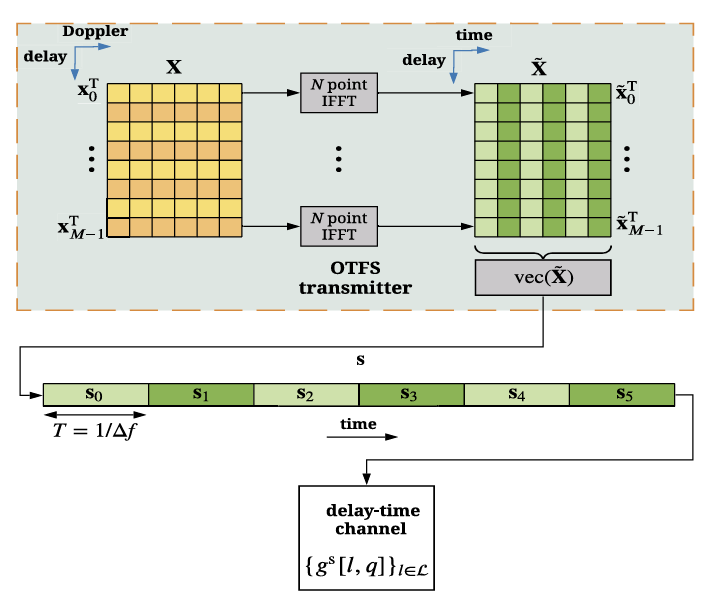

(DELAY-DOPPLER COMMUNICATIONS: Principles and Applications, *Yi Hong, Tharaj Thaj and Emanuele Viterbo*)

This is implemented by the following code:

% Generate the MxN OTFS delay-Doppler frame
X=reshape(tx_info_symbols,M,N);

Im=eye(M);
P=zeros(N*M,N*M);
for j=1:N
    for i=1:M
        E=zeros(M,N);
        E(i,j)=1; 
        P((j-1)*M+1:j*M,(i-1)*N+1:i*N)=E;
    end
end

% OTFS Modulation
X_tilda=X*Fn'; 
s=reshape(X_tilda,1,N*M);

Once the OTFS signal is generated, the transmitted Delay-Doppler Grid can be represented, as well as the corresponding time and frequency domain representation, to analyze the signal behavior. 

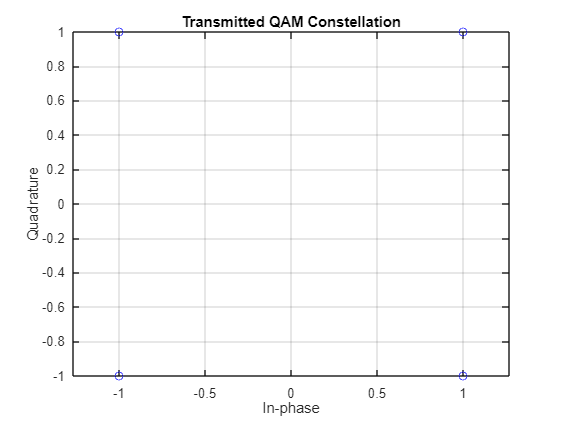

% Plot Transmitted Delay-Doppler Grid
figure;

imagesc(abs(s)); 
colorbar;
title('Transmitted OTFS Delay-Doppler Grid'); 
xlabel('Doppler Bins'); 
ylabel('Delay Bins');

From the previous graph, the **x-axis** represents the **Doppler bins**, which correspond to frequency shifts caused by the movement of the scatters. The **y-axis** represents the **delay bins**, which correspond to different transmission path delays due to multipath propagation. The **color scale** indicates the amplitude (magnitude) of the transmitted signal across different bins, with higher values in yellow and lower values in blue.

Looking at the graph, the **vertical stripe patterns** indicate that the OTFS signal energy is spread over the entire time-frequency grid rather than being localized to specific bins. This spreading across both delay and Doppler domains ensures that the transmitted symbols experience a more uniform **channel gain**, reducing the impact of deep fades and improving robustness in high-mobility environments. Finally, some regions have a dominant bright (yellow) color, suggesting areas where signal energy is higher, which correspond to stronger multipath components.

Now, the final OTFS signal can be represented in the time and frequency domain.

% Time domain representation of the N*M values of the transmitted signal 's'
figure;
subplot(2,1,1)
plot(real(s(1:N*M)), 'b');
title('Signal in the time domain (real)');
xlabel('Samples');
ylabel('Amplitude');
grid on;
axis tight;
%Signal spectrum representation. 
[p_otfs,f_otfs] = pspectrum(s);
f_otfs = f_otfs ./ pi;
subplot(2,1,2)
semilogy(f_otfs, fftshift(p_otfs))
title('OTFS Spectrum');
grid on
xlabel('Frequency');
ylabel('Power (dB)');

The top plot represents the **real part** of the transmitted OTFS signal ***s ***over N×M samples. The signal appears **random-like** but remains bounded within a certain amplitude range. Since OTFS modulates symbols across the **delay-Doppler domain**, the time-domain waveform is a **superposition of multiple frequency components**, leading to this seemingly complex structure. Finally, the **high variability** in amplitude suggests a wide spectral occupation, which is confirmed in the frequency domain analysis.

On the other hand, the bottom plot displays the **power spectral density (PSD)** of the OTFS signal, obtained using **pspectrum**. The **x-axis** represents the **normalized frequency**, while the **y-axis** (on a logarithmic scale) shows the signal power in decibels.The **frequency components are well spread**, indicating that OTFS uses the entire available bandwidth efficiently. There are **no sharp peaks**, suggesting that OTFS avoids excessive concentration of power in specific frequency bands, leading to **better resistance to frequency-selective fading**. The relatively **flat spectrum** suggests that the transmitted signal maintains a uniform power distribution across the bandwidth.

**High- Mobility Channel Generation**

Once the signal has been generated and analyzed, the **high-mobility wireless channel** through which the OTFS signal is going to be transmitted must be generated. 

An EVA Delay Profile is going to be used to generate the channel model, which accounts for **Doppler shifts** and **multipath propagation**, which are crucial factors in high-speed scenarios. The **Extended Vehicular A (EVA) channel model**, is commonly used for LTE and 5G evaluations. Its corresponding propagation delays of the different mulitpath components (in seconds) and the pdp (Power Delay Profile) corresponding to the relative power of each path, are presented in the following table. 

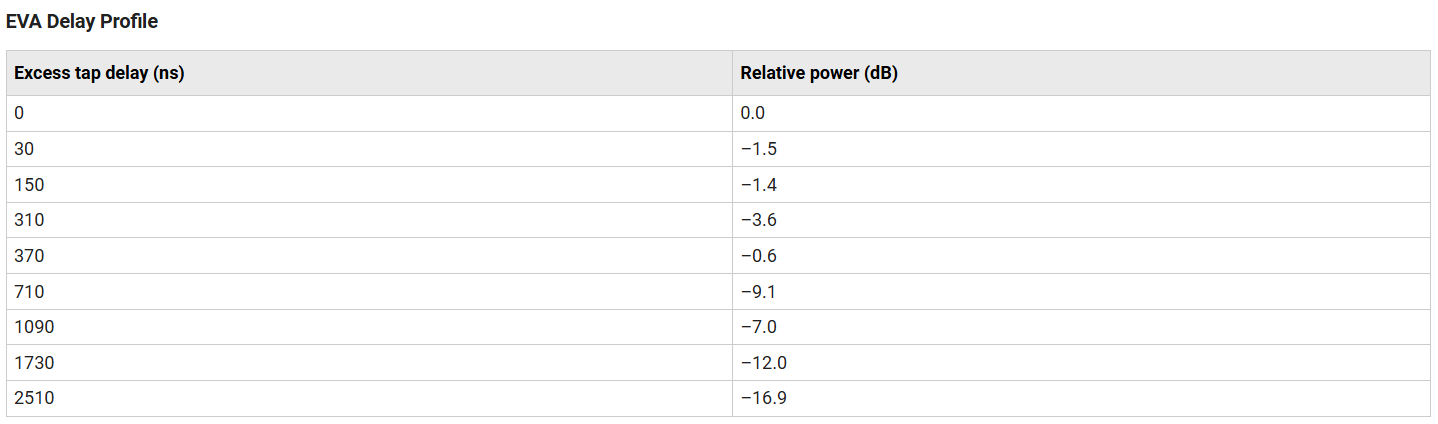

Moreover, it is assumed that the  **User Equipment (UE)** is moving at **100 km/h**. This speed is converted into **meters per second (m/s), **and the **maximum Doppler spread** ($\nu_{\max }$) is calculated using the formula: 


$$\[
\nu_{\max} = \frac{\text{UE speed} \times f_c}{c}
\]
$$


where ***fc ***is the carrier frequency, and ***c*** is the speed of light. This Doppler spread defines the **frequency shift** caused by movement, which is crucial in OTFS since it operates in the **delay-Doppler domain**.

Then, **6 multipath components** (or taps) are assumed, meaning that the signal reflects off **six different objects** before reaching the receiver. The maximum **normalized delay spread** (*l_max*) is **4 delay bins, **and the maximum **Doppler spread** (*k_max*) is **4 Doppler bins**.

The next step is to generate the **channel coefficients** based on **Rayleigh fading**, which models wireless multipath propagation. For these taps, a **uniform power delay profile (PDP)** is assumed, and the coefficients are modeled as **complex Gaussian random variables**:


$$\[
g_i \sim \mathcal{CN}(0,1)
\]
$$


where ***randn(1,taps)*** generates real and imaginary parts of the Gaussian distribution.

After generating the coefficients, the **Delays and Doppler Shifts **are **assigned to each path**. For doing this, the **delays** of the multipath components are assigned **random values** between 0 and *l_max, *ensuring the smallest delay starts from zero. On the other side, the **Doppler shifts** are randomly distributed between **[−kmax ,kmax ]**, assuming a **uniform Doppler spectrum**.

The last step is to generate the discrete-time baseband channel in TDL form. In order to do this, the relation between the actual Doppler response and the sampled time domain channel at each integer delay tap *l ∈ L* can be calculated as: 


$$\[
g^s[l,q] =
\begin{cases} 
\sum_{\kappa \in \mathcal{K}_l} \nu_l(\kappa) z^{\kappa(q-l)} & \text{for } l \in \mathcal{L}, \\
0 & \text{otherwise}.
\end{cases}
\]
$$


where $z^{k\left(q-l\right)}$ represents the phase shift caused by the Doppler effect, where ***z*** is a complex exponential function, and ***νl(κ)*** is the complex channel gain associated with the delay ***l ***and Doppler shift ***k***. It follows a complex Gaussian distribution, meaning it models Rayleigh fading effects in wireless communication. Therefore, considering a time-varying multipath channel of ***P*** paths, where the i-th path (***i =1,...,P***) has channel gain ***gi***,delay shift $\tau_i$, and Doppler shift $\upsilon_i$, the Doppler response at delay shift $l=l_i$ = $\frac{\tau_i }{M\;\Delta f}$  is given as:


$$\[
\nu_l(\kappa) =
\begin{cases} 
g_i, & \text{if } l= l_i = \frac{\tau_i}{M \cdot \Delta f}  , \quad \text{and } \kappa = \kappa_i = \frac{\nu_i}{NT}, \\
0, & \text{otherwise}.
\end{cases}
\]
$$


Coding all these formulas in the next chunk, the final channel coefficients are obtained:

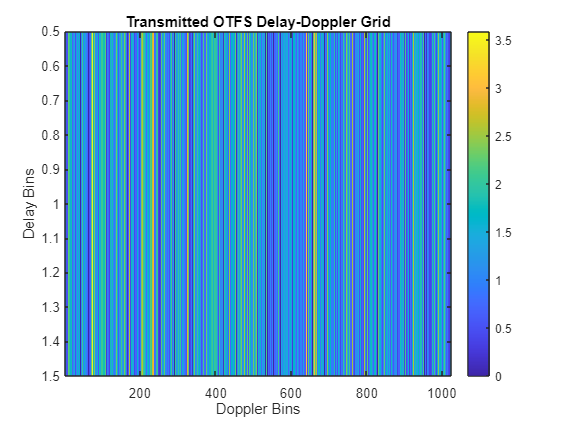

%% CHANNEL
max_UE_speed_kmh=100; % maximum user equipment speed
max_UE_speed = max_UE_speed_kmh*(1000/3600); %change to m/s
% maximum Doppler spread (one-sided)
nu_max = (max_UE_speed*fc)/(c);



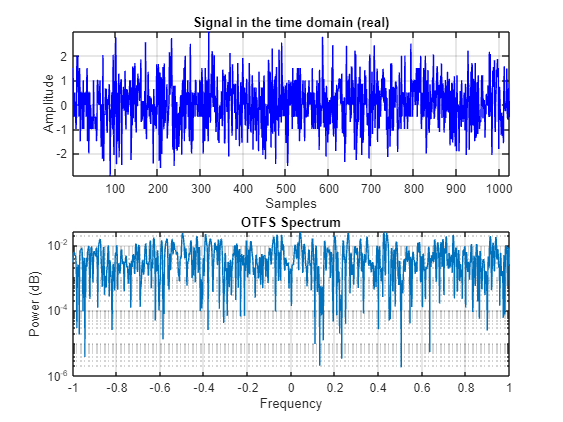

%EVA model
delays = [0, 30, 150, 310, 370, 710, 1090, 1730, 2510]*1e-9;
pdp = [0.0, -1.5, -1.4, -3.6, -0.6, -9.1, -7.0, -12.0, -16.9];

% dB to linear scale
pdp_linear = 10.^(pdp/10); 
pdp_linear = pdp_linear/sum(pdp_linear);

% number of propagation paths
taps=6;

% maximum normalized delay and Doppler spread
l_max=4; 
k_max=4;

% Generating channel coefficients (Rayleigh fading) with uniform pdp
g_i = sqrt(1/taps).*(sqrt(1/2) * (randn(1,taps)+1i*randn(1,taps)));

% Generating delay taps uniformly from [0,l_max]
l_i = [randi([0,l_max],1,taps)]; 
l_i= l_i-min(l_i);


% Generating Doppler taps (assuming uniform spectrum [-k_max,k_max])
k_i = k_max-2*k_max*rand(1,taps);

z=exp(1i*2*pi/N/M); %Phase rotation due to the Doppler
delay_spread=max(l_i);

% Generate discrete-time baseband channel in TDL form 
gs=zeros(delay_spread+1,N*M);

for q=0:N*M-1
    for i=1:taps
        gs(l_i(i)+1,q+1)=gs(l_i(i)+1,q+1)+g_i(i)*z^(k_i(i)*(q-l_i(i)));
    end
end


Now, the channel impulse response can be plotted: 

% Plot Channel Impulse Response
figure; 
subplot(2,1,1)
stem(abs(gs(:,1)));
title('Channel Impulse Response'); 
xlabel('Delay Taps'); 
ylabel('Magnitude'); 
grid on;
xlim([0 5])
subplot(2,1,2)
imagesc(abs(gs));  % Plot the magnitude of the channel impulse response
xlabel('Time index');
ylabel('Delay index');
title('Complete Channel Module'); 
colorbar;  % To show the magnitude scale

The values presented above correspond to the magnitude of the impulse response at various delay indices. The top plot corresponds to the ** Channel Impulse Response, **where four prominent spikes located at distinct delay tap positions can be seen. Each spike represents a multipath component, with different magnitudes indicating their relative power, characteristic of the EVA. The variation in tap magnitudes reflects the power delay profile (PDP), where stronger paths carry more energy while weaker taps decay faster. At the graph it can be seen how the channel is modeled with a maximum normalized delay spread of 4 symbols, as it was defined in the previous parameters. On the other hand, the bottom plot, corresponds to the **Channel Time-Delay Response. **It reveals horizontal bands with alternating yellow (strong) and blue (weak) regions. Some delay indices show consistent signal presence, while others are weaker or absent. The periodic color variation across the time axis is a result of Doppler-induced phase shifts. Moreover, the strong and stable bands indicate dominant multipath components with minimal fluctuation, while the alternating color pattern (due to phase rotation in Doppler) suggests the presence of frequency shifts, which align with the Doppler spread (***k_i*** values). Finally, it is important to note that gaps in certain delay indices indicate that not all delay taps contribute equally, some paths may experience deep fading or insignificance.

Finally, the **discrete-time baseband channel matrix** G can be built, which represents the time-domain channel response for the OTFS system. The matrix G maps the channel’s **time-domain impulse response** into a matrix form. Each entry ***G(i,j) ***represents the channel's response from time index j to i, essentially a convolution structure, therefore, the non-zero elements correspond to active multipath components.  This transformation is crucial when simulating how the channel distorts the OTFS signal in practice, and it will be key in performing **matrix multiplication** for data recovery or equalization.

This matrix G,  has ***lmax + 1*** non zero diagonal and subdiagonals, with elements in each subdiagonal given by:


$$\[
G[q, q - \ell] =
\begin{cases}
    g_s[\ell, q] & \text{if} \; \ell \leq q \leq N M - 1 \\
    0 & \text{otherwise}
\end{cases}
\]
$$


% Generate discrete-time baseband channel matrix
G=zeros(N*M,N*M);
for q=0:N*M-1
    for ell=0:delay_spread
        if(q>=ell)
            G(q+1,q-ell+1)=gs(ell+1,q+1);
        end
    end
end

figure;
imagesc(abs(G)); 
colorbar;
title('Time-Domain Channel Matrix G');
xlabel('Time Index'); 
ylabel('Time Index');

As it can be seen in the graph, the matrix has a prominent diagonal line with non-zero values, while the rest of the matrix appears mostly zero.This diagonal pattern suggests, as it was expected, that the channel is predominantly **time-invariant** or exhibits **minimal dispersion** in the time domain. 

Therefore, the strong diagonal with the rest of values being 0 implies that the channel behaves similarly to an **ideal delay channel** with minimal distortion, resembling a **sparse channel**. Since the EVA model has multiple delay taps, this result suggests that most energy is concentrated in the **first few taps**, with less contribution from larger delays. Finally, the limited spread around the diagonal also reflects a **short coherence time** with controlled Doppler shifts, which aligns with the defined speed (100 km/h).

Now, the matrix G is going to be transformed with a permutation matrix P, following the next equation: 


$$\[
\tilde{H} = P G P^T
\]
$$


The transformation  **rearranges the entries** of G to match the **delay-time domain** representation, which is crucial in OTFS modulation. OTFS is designed to operate in the **delay-Doppler domain**, but since this involves spreading symbols across both delay and time axes, this permutation matrix step is necessary for accurate mapping. The resulting matrix $\overset{~}{H}$ is the **delay-time channel matrix**, where each element now corresponds to the channel's impact on a specific **delay tap** and **time index**.

% generate delay-time channel matrix 
H_tilda=P*G*P.';

figure;
imagesc(abs(H_tilda)); 
colorbar;
title('Delay-Time Channel Matrix H');
xlabel('Time Index'); 
ylabel('Delay Index');

As it can be seen in the representation above, the additional lines appearing in the plot, compared with the original G graph, indicate that the permutation process is redistributing the nonzero elements of G across different delay indices. This is what it was expected, since the permutation matrix P has been designed to reorder elements such that the delay-time representation correctly aligns with the OTFS framework. Therefore, instead of just a diagonal structure (seen in the original G), P reorganizes values into multiple shifted diagonals. In fact, the additional lines represent the different delay taps $l_i$ that were defined when generating the channel.Since different paths experience different delays, the channel matrix in the delay-time domain has nonzero values corresponding to these delays.

For this reason, while the **first plot (Time-Domain Channel Matrix ****G****)** showed a mostly diagonal structure because each time index was mainly affected by its direct delay, the **second plot (Delay-Time Channel Matrix ****H****)** correctly shows multiple shifted diagonal structures, indicating multiple paths with distinct delays contributing to the signal.

**From time representation to Doppler representation:**

The previous Delay-Time domain channel matrix $\overset{~}{H}$ describes how different delay taps evolve over time. However, the objective to proceed is to obtain the **Delay-Doppler domain channel matrix H, **that reveals how the channel varies in both delay and Doppler shifts. To move from the Delay-Time to the Delay-Doppler representation, the Discrete Fourier Transform (DFT) is applied along the time dimension (which corresponds to frequency in the dual domain). For doing this, the **Kronecker product** with the DFT matrix FN (**DFT matrix** of size N×N) is used, applying its formula:


$$\[
H = (\mathbf{I}_M \otimes \mathbf{F}_N) P^T G P (\mathbf{I}_M \otimes \mathbf{F}_N^H)
\]
$$


% generate delay-Doppler channel matrix
H=kron(Im,Fn)*(P'*G*P)*kron(Im,Fn');
figure();
imagesc(abs(H)); colorbar;
title('Delay-Doppler Channel Matrix H');
xlabel('Doppler Index'); 
ylabel('Delay Index');

In the graph above, the x- axis represents the Doppler shifts due to motion. Different Doppler indices correspond to different frequency shifts in the received signal, and the structure it is obtained suggests the presence of multiple Doppler components per delay tap. The y-axis represents the delay index, which is the delay spread of different multipath components. Higher delay indices correspond to paths that arrive later. As it can be seen, there are **Multiple** **Off-Diagonal Lines, **where each multipath component has a delay and a Doppler shift. Multiple lines appeared because multiple **delay taps** and **Doppler shifts **have been defined at the beginning of the code. Moreover, the structure shows that each delay tap is spread across multiple Doppler bins.

Finally, the presence of shifted diagonal structures suggests that although most paths have small Doppler shifts, they are spread across multiple bins, which aligns with the uniform Doppler shifts that were introduced before. 

The last step consists of obtaining the final received signal. In order to do this, the transmitted signal *x* is **passed through the Delay-Doppler channel matrix ****H:**


$$y=H*x$$


This operation models the effect of multipath fading **in the Delay-Doppler domain, **and the output *y *represents the received signal **before** applying any transformation back to the time domain. The resulting signal *y, *must be transformed back to the time domain, using the expression: 


$$\[
r = P \cdot (\mathbf{I}_M \otimes \mathbf{F}_N^H) \cdot y
\]
$$


where;

- ${F_N }^H$**:** Converts the Doppler-domain signal back to the **time-frequency domain**.

- $I_M$**⊗**${F_N }^H$**:** Ensures this transformation is applied to all subcarriers.

- **Permutation Matrix *****P*****:** Reorders the signal to match the original OTFS grid.

- **Final Output *****r *****:** Now it represents the received signal **in the time-frequency domain**, ready for demodulation and equalization.

Finally, the **Signal-to-Noise Ratio (SNR)** is computed using the **average QAM symbol energy, **and a **Gaussian noise** is generated with variance ${\sigma_w }^2$. Then, the noise is added to*** r***, simulating the effect of a real-world wireless channel.

In the following plot, the received signal *r* is plotted in the **IQ plane**. As it can be seen, since equalization hasn't been applied yet, the symbols appear distorted due to channel effects and noise. This gives a **visual representation** of how the channel has impacted the transmitted QAM symbols, resulting in a constellation where it is impossible to see anything. 

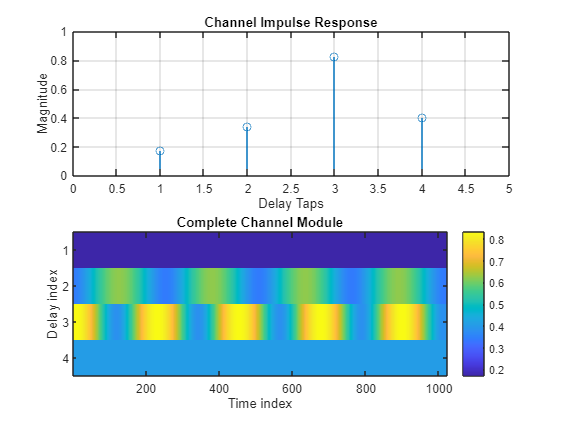

% Method 4: Using the delay-Doppler channel matrix (H) 
x=reshape(X.',N*M,1);
y=H*x;
r=P*kron(Im,Fn')*y;


% Add AWGN


% average QAM symbol energy
Es = mean(abs(qammod(0:mod_size-1,mod_size).^2));
% SNR=Es/noise power
SNR=10.^(SNR_dB/10);
% noise power
sigma_w_2=Es/SNR;

% generate Gaussian noise samples with variance=sigma_w_2
noise = sqrt(sigma_w_2/2)*(randn(N*M,1) + 1i*randn(N*M,1));
% add AWGN to the received signal
r=r+noise;

% Plot Received Constellation before Equalization
figure; 
scatter(real(r), imag(r), 'filled');
title('Received Constellation (Before Equalization)'); 
xlabel('In-phase'); 
ylabel('Quadrature'); 
grid on;

**OTFS Demodulation **

This last step consists of applying **equalization** to recover the transmitted OTFS symbols. 

Firstly, at the receiver, the received ***NM ***complex samples vector is obtained as:


$$\mathbf{r} = \left[ \begin{array}{c} ro\\
\vdots \\
r_{N-1}
\end{array} \right] = r[q], \quad q = 0, \dots, NM-1$$


where $\( r_n \in \mathbb{C}^{M \times 1} \) for \( n = 0, \dots, N-1 \)$.

Then, the vector ***r*** is converted to the delay-time matrix $\( \tilde{Y} \in \mathbb{C}^{M \times N} \) $ as $\[
\tilde{Y} = \mathbf{G}_{rx} \cdot ({vec}^{-1}_{M,N}(\mathbf{r}))
\]$, where the operator $\( \({vec}^{-1}_{M,N}(\mathbf{r}) \)$ converts $\( \mathbf{r} \in \mathbb{C}^{NM \times 1} \) to an \( M \times N \) matrix.$ And, the diagonal matrix $\( \mathbf{G}_{rx} \) $is the receiver pulse shaping matrix, defined as 


$$\[
\mathbf{G}_{rx} = ({diag} \Big( g_{rx}(0), g_{rx}(T/M), \dots, g_{rx}((M-1)T/M) \Big) \in \mathbb{C}^{M \times M}.
\]$$


However, this process can be simplified for the rectangular pulse shaping waveforms where $\( \mathbf{G}_{rx} = \mathbf{I}_M \)$, which reduces the previous equation to: 


$$\[
\tilde{Y} = ({vec}^{-1}_{M,N}(\mathbf{r})) \quad \text{or} \quad \mathbf{r} = ({vec}(\tilde{Y})).
\]$$


Then, the time-frequency domain received samples matrix $\( \mathbf{Y}_{\text{tf}} \in \mathbb{C}^{M \times N} \) $is obtained by performing an M-point DFT operation on the delay-time samples:


$$\[
\mathbf{Y}_{\text{tf}} = \mathbf{F}_M \cdot \tilde{Y}.
\]$$


The previous operations together constitute the Wigner transform.  An SFFT operation is performed to obtain the delay-Doppler domain symbols. Finally, the SFFT operation in cascade with the Wigner transform can be simplified as:


$$\[
\mathbf{Y} = \mathbf{F}_M^\dagger \cdot \mathbf{Y}_{\text{tf}} \cdot \mathbf{F}_N = \tilde{Y} \cdot \mathbf{F}_N.
\]$$


All this process of implementing the OTFS receiver based on the DZT using rectangular pulse shaping waveform, can be summarize in the following scheme. 

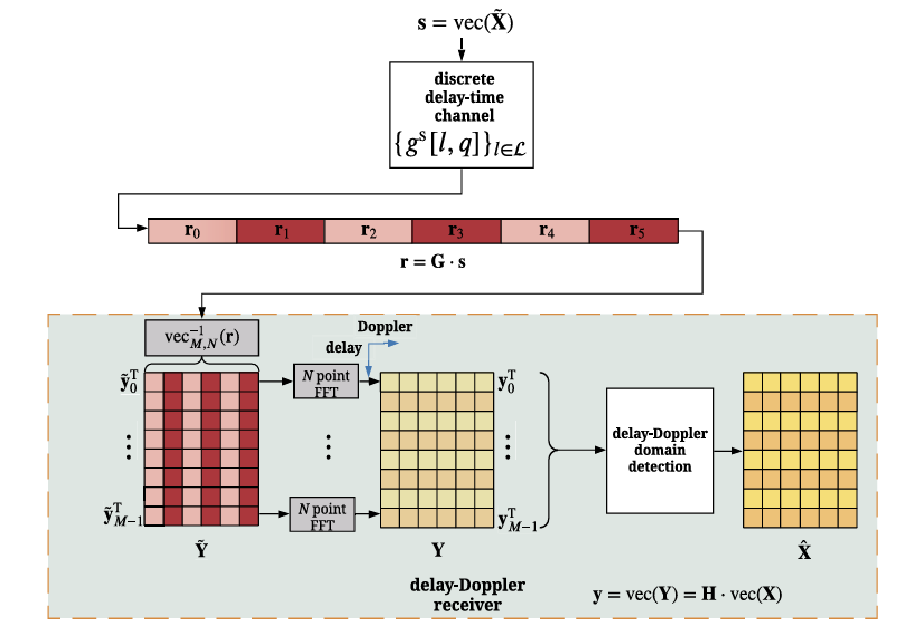

(DELAY-DOPPLER COMMUNICATIONS: Principles and Applications, *Yi Hong, Tharaj Thaj and Emanuele Viterbo*)

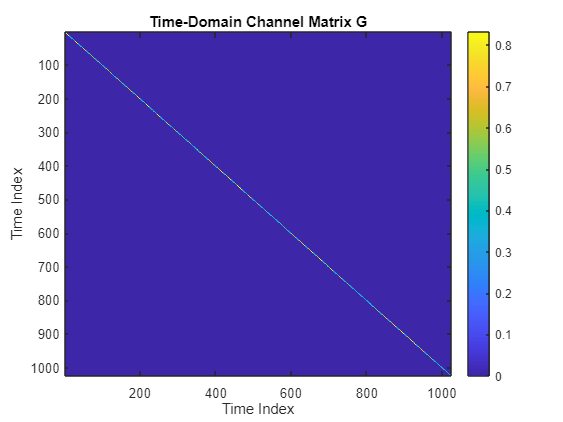

Y_tilda=reshape(r,M,N); 
Y=Y_tilda*Fn;

**Delay-Doppler domain LMMSE detection**

The last step consists of estimating the transmitted symbols, to recover the original constellation. In order to do this, a **Delay-Doppler domain LMMSE detection **is going to be performed. 

Considering that the input-output relation is defined as following: 


$$y=H*x+z$$


the LMMSE estimate of ***x*** is given by the formula:


$$\[
x = (\mathbf{H}^\dagger \mathbf{H} + \sigma_w^2 \mathbf{I}_{MN})^{-1} \mathbf{H}^\dagger y.
\]$$


The previous operation requires inverting an *NM x NM* matrix, which is of high complexity, even if the matrix *H* is sparse. This process is implemented in the following code cell. 

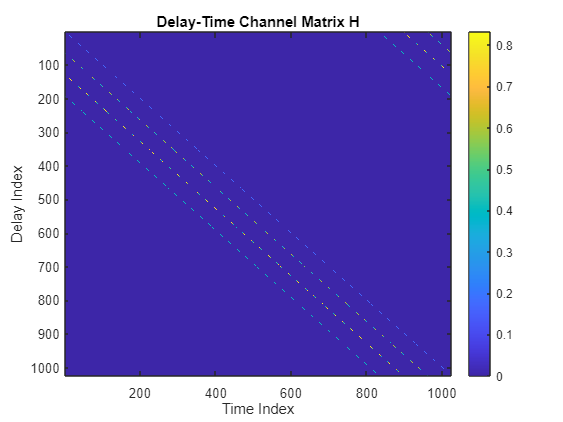

% Vectorize Y
y=reshape(Y.',N*M,1);
% Estimated delay-Doppler matrix 
x_hat=(H'*H+sigma_w_2*eye(M*N))^(-1)*(H'*y);

% Plot Received Constellation transmitted, received, and after Equalization
figure; 
subplot(1,3,1)
scatter(real(tx_info_symbols), imag(tx_info_symbols), 'filled');

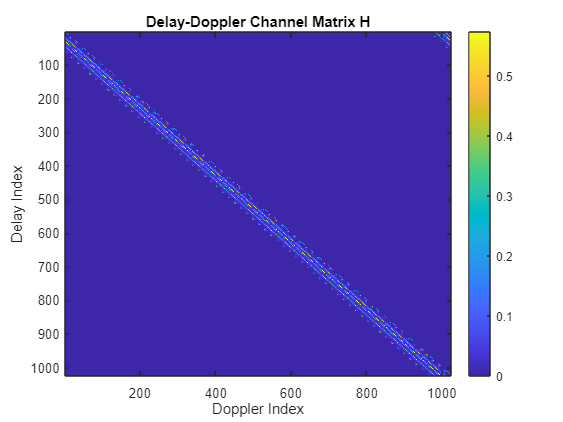

title('Transmitted Constellation'); 
xlabel('In-phase'); 
ylabel('Quadrature'); 
grid on;

subplot(1,3,2)
scatter(real(r), imag(r), 'filled');
title('Received Constellation (Before Equalization)'); 
xlabel('In-phase'); 
ylabel('Quadrature'); 
grid on;

subplot(1,3,3)

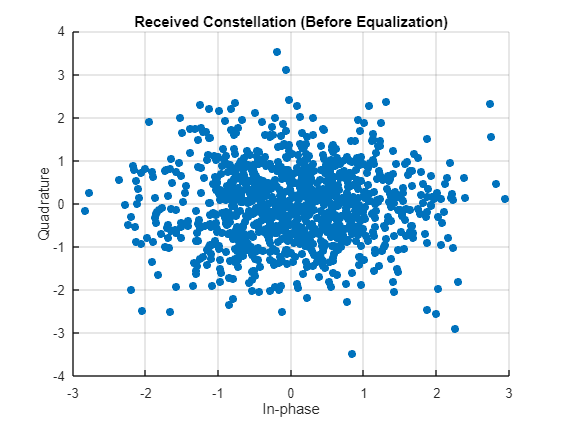

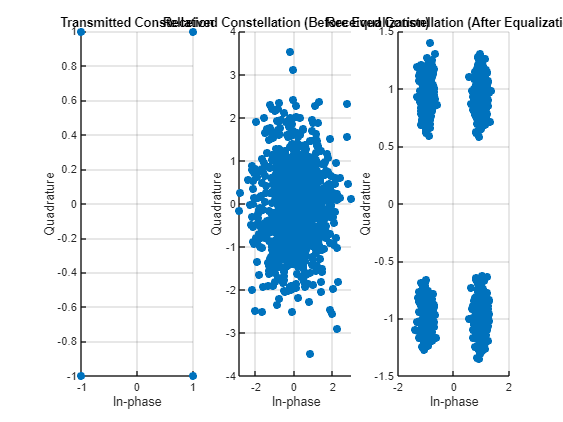

scatter(real(x_hat), imag(x_hat), 'filled');
title('Received Constellation (After Equalization)'); 
xlabel('In-phase'); 
ylabel('Quadrature'); 
grid on;

After performing the **Delay-Doppler domain LMMSE detection**, the estimated transmitted symbols are obtained. Thanks to this process, the distortions introduced by the wireless channel are compensated, including both the multipath fading and Doppler shifts. 

Looking at the results presented in the previous graph, the received constellation after equalization appears **perfectly defined**, meaning that the estimated symbols are very close to the original transmitted ones. Despite this, due to the presence of **additive white Gaussian noise (AWGN)** and the limitations of the equalization process, the constellation points are slightly scattered around their ideal positions. Clearly this scattering introduces noise, making the points a bit different than the original transmitted 4-QAM constellation (presented at the first plot), which consists of exactly **four points in the corners of the complex plane.**

To conclude, the final received constellation visually confirms the effectiveness of the **LMMSE equalization**, as it restores the QAM structure while still exhibiting noise effects from the channel.